## Solution to Question 1

Transfer function for the system

d = 1; I = 1;
s = tf('s');
sys = d/(I*s^2)


sys =
 
   1
  ---
  s^2
 
Continuous-time transfer function.



Apply step input and get analytical solution using ilaplace():

syms s
sysWithStep = d/(I*s^3)

$$sysWithStep = \frac{1}{s^{3}}$$

analyticalSoln = ilaplace(sysWithStep)

$$analyticalSoln = \frac{t^{2}}{2}$$

Plot analytical solution

tspan = linspace(0,10,1000);
syms t
analyticalSoln = subs(analyticalSoln,t,tspan);
figure(1)
plot(tspan,analyticalSoln,'-b','LineWidth',3)

Use step function to find solution

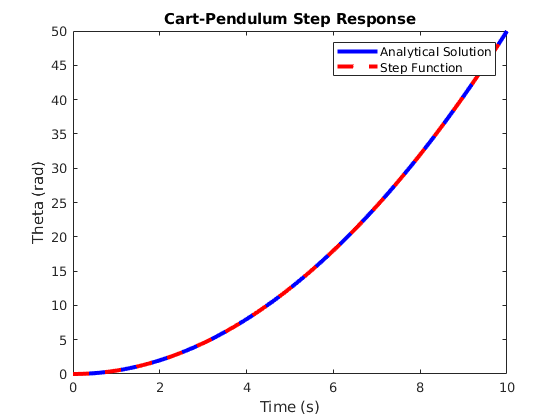

stepFuncSoln = step(sys,tspan);
hold on
plot(tspan,stepFuncSoln,'--r','LineWidth',3)
legend('Analytical Solution','Step Function')
xlabel('Time (s)') ; ylabel('Theta (rad)') ; title('Cart-Pendulum Step Response') ; 

Square Wave Input

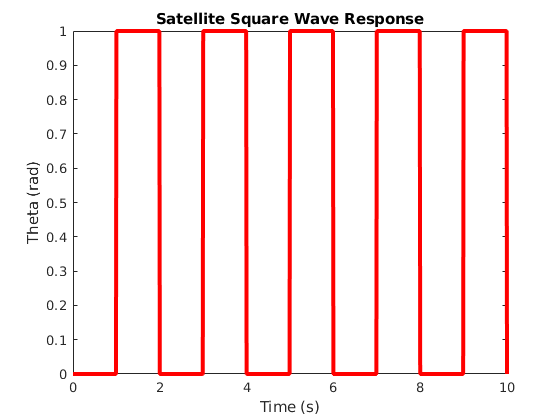

% generate the square wave input function
[squareInput,tspan] = gensig('square',2,10,0.01);
figure(2)
plot(tspan,squareInput,'-r','LineWidth',3)
xlabel('Time (s)') ; ylabel('Theta (rad)') ; title('Satellite Square Wave Response') ; 

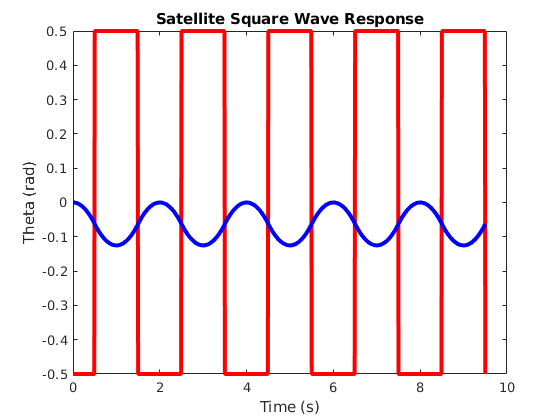

drawnow
squareInput = squareInput-1/2;
tspan = tspan-1/2;
squareInput(tspan < 0) = [];
tspan(tspan<0) = [];
response = lsim(sys,squareInput,tspan);
figure(2)
plot(tspan,squareInput,'-r','LineWidth',3)
hold on
plot(tspan,response,'-b','LineWidth',3)
xlabel('Time (s)') ; ylabel('Theta (rad)') ; title('Satellite Square Wave Response') ; 

## Solution to Question 2

Transfer function for the system:

s = tf('s') ; % need s to represent a transfer function for the step response
num = 1 ; 
den = [-5, -20] ; 
sys = tf(num,den) 


sys =
 
     -1
  --------
  5 s + 20
 
Continuous-time transfer function.



% sys = 1 / ( (3*s^2) + 20 ) 

Apply step input and get analytical solution using ilaplace():

syms S % using capital letter instead for symbolic s which is required for ilaplace
% num2 = 1 ; 
% den2 = [3,0,0,20] ; 
% step_sys = tf(num2,den2) 
step_sys = 1 / ( (-5*S^3) - 20*S ) 

$$step\_sys = -\frac{1}{5\,S^{3}+20\,S}$$

step_sys_TD = ilaplace(step_sys) 

$$step\_sys\_TD = \frac{\cos\left(2\,t\right)}{20}-\frac{1}{20}$$

Plot the analytical solution against MATLAB's built-in step response function: 

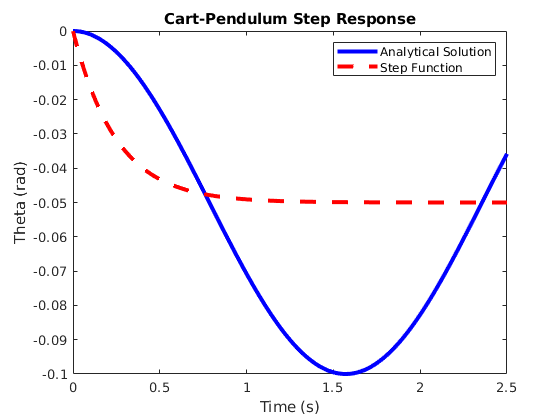

syms t
time = (0:0.01:2.5)' ; 
step_sys_TD_array = subs(step_sys_TD,t,time) ; % analytical solution
[Yt, ts] = step(sys,time) ; % matlab solution

% plot
figure(3)
plot(time,step_sys_TD_array,'-b','LineWidth',3)
hold on
plot(ts,Yt,'--r','LineWidth',3)
legend('Analytical Solution','Step Function')
xlabel('Time (s)') ; ylabel('Theta (rad)') ; title('Cart-Pendulum Step Response') ;